%CS170 Project 2 Live Script File
addpath('E:\Winter2021\CS170\Project2\FeatureSelectionWithNN')

%datafile = 'CS170_largetestdata__2.txt';
datafile = 'CS170_SMALLtestdata__42.txt';
%datafile = 'CS170_small_special_testdata__95.txt';

%read data from file
data = readmatrix(datafile);

disp(['Reading Data Set from file "', datafile,'"' ]);

Reading Data Set from file "CS170_SMALLtestdata__42.txt"



disp(['Read file of ',num2str(size(data,1)),' data points with ',num2str(size(data,2)-1),' features each.']);

Read file of 300 data points with 10 features each.



%find best performing combination of features through Search
disp(['> Starting forward search <'])

> Starting forward search <


tic;
[best_features_for , ordered_features_for, performances_for]= Forward_Search(data(:,2:size(data,2)),data(:,1));

On level 1 of search tree
--Considering adding feature 1
----Accuracy: 0.64667
--Considering adding feature 2
----Accuracy: 0.67
--Considering adding feature 3
----Accuracy: 0.69
--Considering adding feature 4
----Accuracy: 0.68
--Considering adding feature 5
----Accuracy: 0.69
--Considering adding feature 6
----Accuracy: 0.61
--Considering adding feature 7
----Accuracy: 0.65333
--Considering adding feature 8
----Accuracy: 0.63667
--Considering adding feature 9
----Accuracy: 0.83333
--Considering adding feature 10
----Accuracy: 0.65
On level 1, added feature 9.
On level 2 of search tree
--Considering adding feature 1
----Accuracy: 0.8
--Considering adding feature 2
----Accuracy: 0.79333
--Considering adding feature 3
----Accuracy: 0.81333
--Considering adding feature 4
----Accuracy: 0.76667
--Considering adding feature 5
----Accuracy: 0.91333
--Considering adding feature 6
----Accuracy: 0.82333
--Considering adding feature 7
----Accuracy: 0.78333
--Considering adding feature 8
----Accu

toc;

Elapsed time is 19.543502 seconds.




disp(['> Starting backward search <'])

> Starting backward search <


tic;
[best_features_back , ordered_features_back, performances_back]= Backward_Search(data(:,2:size(data,2)),data(:,1));

On level 1 of search tree
--Considering dropping feature 1
----Accuracy: 0.69
--Considering dropping feature 2
----Accuracy: 0.7
--Considering dropping feature 3
----Accuracy: 0.67333
--Considering dropping feature 4
----Accuracy: 0.69667
--Considering dropping feature 5
----Accuracy: 0.67
--Considering dropping feature 6
----Accuracy: 0.70333
--Considering dropping feature 7
----Accuracy: 0.68
--Considering dropping feature 8
----Accuracy: 0.69333
--Considering dropping feature 9
----Accuracy: 0.66667
--Considering dropping feature 10
----Accuracy: 0.69
On level 1, dropped feature 6.
On level 2 of search tree
--Considering dropping feature 1
----Accuracy: 0.7
--Considering dropping feature 2
----Accuracy: 0.69667
--Considering dropping feature 3
----Accuracy: 0.69333
--Considering dropping feature 4
----Accuracy: 0.71
--Considering dropping feature 5
----Accuracy: 0.7
--Considering dropping feature 7
----Accuracy: 0.73
--Considering dropping feature 8
----Accuracy: 0.73667
--Consideri

toc;

Elapsed time is 25.224727 seconds.


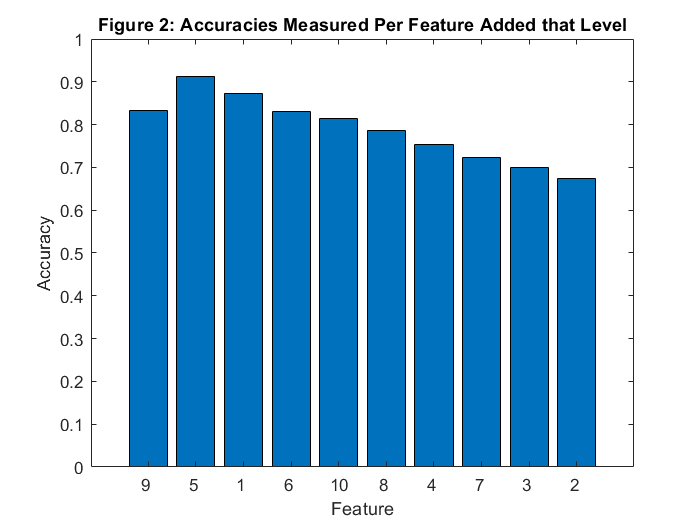

bar(performances_for)
hold on;

set(gca,'xticklabel',ordered_features_for);
title("Figure 2: Accuracies Measured Per Feature Added that Level");
xlabel('Feature');
ylabel('Accuracy');
hold off;

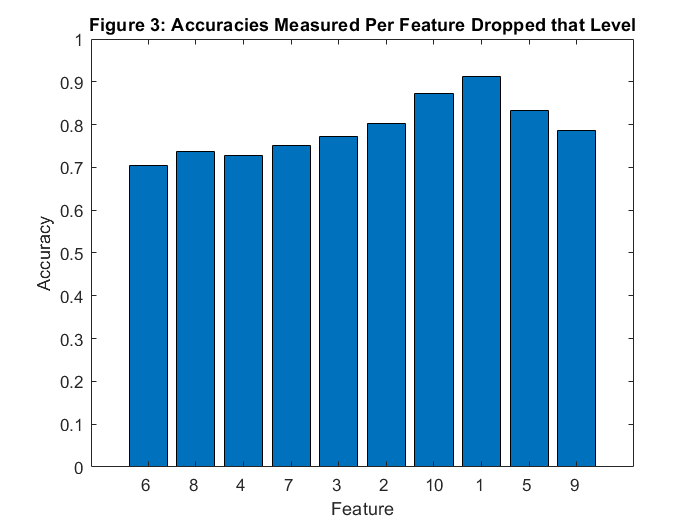


bar(performances_back)
hold on;

set(gca,'xticklabel',ordered_features_back);
title("Figure 3: Accuracies Measured Per Feature Dropped that Level");
xlabel('Feature');
ylabel('Accuracy');
hold off;

disp(['Best Features found by Forward Selection: ',num2str(best_features_for)]);

Best Features found by Forward Selection: 9  5


disp(['Performance: ',num2str(max(performances_for))]);

Performance: 0.91333


disp(['Best Features found by Forward Selection: ',num2str(best_features_back)]);

Best Features found by Forward Selection: 5  9


disp(['Performance: ',num2str(max(performances_back))]);

Performance: 0.91333


if max(performances_for) >= max(performances_back)
    best_features = best_features_for;
    best_performance = max(performances_for);
else
    best_features = best_features_back;
    best_performance = max(performances_back);
end
disp(['Best Features found Overall: ',num2str(best_features_for)]);

Best Features found Overall: 9  5


disp(['Best Performance Overall: ',num2str(max(performances_for))]);

Best Performance Overall: 0.91333


%data(:,best_features) = []
%[best_features , ordered_features, performances]= Forward_Search(data(:,2:size(data,2)),data(:,1))

%[best_features]



function [best_features, ordered_features, performances] = Backward_Search(data,class)
    best_feature_accuracies = [];
    current_set_of_features = 1:size(data,2);
    set_of_dropped_features = [];
    for i = 1:size(data,2)
        disp(['On level ',num2str(i),' of search tree']);
        feature_to_drop_at_this_level = [];
        best_so_far_accuracy = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(set_of_dropped_features,k))
                disp(['--Considering dropping feature ', num2str(k)]);
                accuracy = Leave_One_Out_Cross_Validation(data,class,setdiff(current_set_of_features,[set_of_dropped_features,k]));
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_so_far_accuracy
                    best_so_far_accuracy = accuracy;
                    feature_to_drop_at_this_level = k;
                end
            end
        end
        set_of_dropped_features(i) = feature_to_drop_at_this_level;
        best_feature_accuracies(i) = best_so_far_accuracy;
        [~,ind] = find(current_set_of_features == feature_to_drop_at_this_level);
        current_set_of_features(ind) = [];
        disp(['On level ', num2str(i),', dropped feature ',num2str(feature_to_drop_at_this_level),'.']);

    end
    [~,ind] = max(best_feature_accuracies);
    ordered_features = set_of_dropped_features;
    performances = best_feature_accuracies;
    best_features = set_of_dropped_features;
    best_features(1:ind) = [];
end

function [best_features, ordered_features, performances] = Forward_Search(data,class)
    best_feature_accuracies = [];
    current_set_of_features = [];
    for i = 1:size(data,2)
        disp(['On level ',num2str(i),' of search tree']);
        feature_to_add_at_this_level = [];
        best_so_far_accuracy = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(current_set_of_features,k))
                disp(['--Considering adding feature ', num2str(k)]);
                accuracy = Leave_One_Out_Cross_Validation(data,class,[current_set_of_features,k]);
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_so_far_accuracy
                    best_so_far_accuracy = accuracy;
                    feature_to_add_at_this_level = k;
                end
            end
        end
        current_set_of_features(i) = feature_to_add_at_this_level;
        best_feature_accuracies(i) = best_so_far_accuracy;
        disp(['On level ', num2str(i),', added feature ',num2str(feature_to_add_at_this_level),'.']);

    end
    [~,ind] = max(best_feature_accuracies);
    best_features = current_set_of_features(1:ind);
    ordered_features = current_set_of_features;
    performances = best_feature_accuracies;
end

%Performs data separatation and calls NN to find the total accuracies of
%of given set of features
function accuracy = Leave_One_Out_Cross_Validation(data,class,current_set_of_features)
    %edit to change cross validation group size    
    cross_cut = size(data,1);
    cut_size = size(data,1)/cross_cut;
    
    partial_acc = 0;
    for i = 1:cross_cut
        itt = (i-1)*cut_size + 1;
        itt2 = i*cut_size;
        test_data = data(itt:itt2,:);
        train_data = data(1:itt-1,:);data(itt2+1:size(data,1),:);
        test_class = class(itt:itt2);
        train_class = class(1:itt-1,:);data(itt2+1:size(data,1));
        partial_acc = partial_acc + NN(train_data,test_data,train_class,test_class,current_set_of_features);
    end
    accuracy = partial_acc/cross_cut;
end

%performs 1-Nearest Neighbor on given test set, comparing it to
function accuracy = NN(train_data,test_data,train_class, test_class, features) %k in this case is the amount of neighbors to consider
    sum_accuracy = 0;
    for i = 1:size(test_data,1) %for each point in the test set
        nearest_neighbor_class = 0;
        nearest_neighbor_dist = intmax;
        for y = 1:size(train_data,1) %compare it to the points in the train set
            dist = sqrt(sum((test_data(i,features) - train_data(y,features)).^2));
            if dist < nearest_neighbor_dist %and find the nearest point, record class and distance
                nearest_neighbor_class = train_class(y);
                nearest_neighbor_dist = dist;
            end
        end
        if nearest_neighbor_class == test_class(i) %if the nearest point classifies it right, it is accurate
            sum_accuracy = sum_accuracy +1;
        end
    end
    accuracy = sum_accuracy/size(test_data,1);
end